% Import instron CSV data 
folder = "data/four_circular_test/";
if 1 % Wrap in an "if" so the warnings all print at the end
    tab_instron_1 = readtable(folder + "FourCircular-10mm_to_40mm_1.csv");
    tab_instron_2 = readtable(folder + "FourCircular-10mm_to_40mm_2.csv");
end

instron_data_tables = {tab_instron_1, tab_instron_2};

% Import pressure CSV data
tab_pressures_1 = readtable(folder + "18-08-2023-17-49-18.txt");
tab_pressures_2 = readtable(folder + "18-08-2023-18-10-07.txt");
tab_pressures_1 = tab_pressures_1(1:end-1, :);
tab_pressures_2 = tab_pressures_2(1:end-1, :);
%tab_pressures_1.Time = tab_pressures_1.Time - 0.3 * 1e4; % Manual time alignment correction
pressure_tables = {tab_pressures_1, tab_pressures_2};

% Batch process all datasets
n_datasets = length(pressure_tables);
combined_datasets = cell(1, n_datasets);
for i = 1 : n_datasets
    combined_datasets{i} = process_test(instron_data_tables{i}, pressure_tables{i});
end

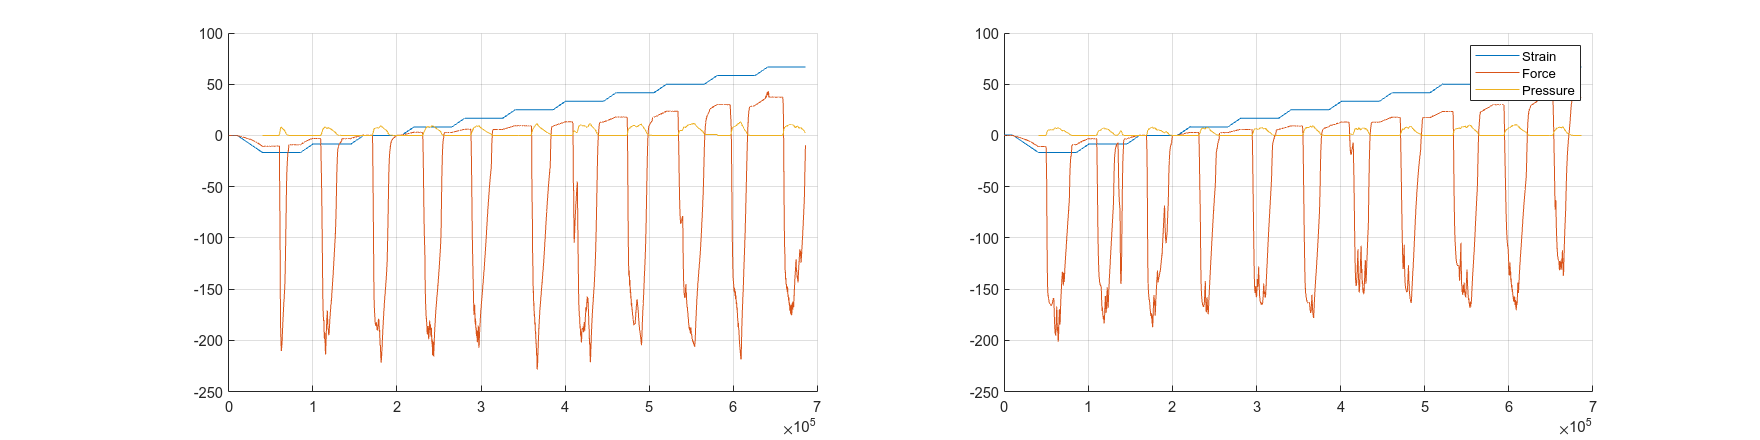

fig = figure();
set(fig, "Position", [0, 0, 1600, 400]);
for i = 1 : length(combined_datasets)
    subplot(1, length(combined_datasets), i);
    hold on
    
    dataset_i = combined_datasets{i};
    plot(dataset_i.Time, dataset_i.TensileStrain_Displacement_);
    plot(dataset_i.Time, dataset_i.Force);
    plot(dataset_i.Time, dataset_i.Pressure);
    grid on
end
legend("Strain", "Force", "Pressure")

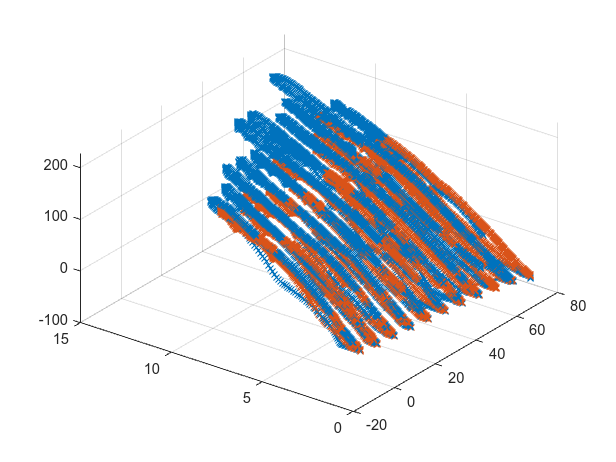

figure()
hold on;
for i = 1 : length(combined_datasets)
    dataset_i = combined_datasets{i};

    i_holding = mod(dataset_i.Displacement, 5) < 0.1;
    dataset_i_holding = dataset_i(i_holding, :);
    scatter3(...
        dataset_i_holding.TensileStrain_Displacement_,...
        dataset_i_holding.Pressure,...
        -dataset_i_holding.Force,...
        'x' ...
    )
end
view(-35, 45)
grid on

all_datasets = [combined_datasets{1}; combined_datasets{2}];
x = all_datasets.TensileStrain_Displacement_;
y = all_datasets.Pressure;
z = all_datasets.Force;

% Fit the surface
[xData, yData, zData] = prepareSurfaceData( x, y, z );

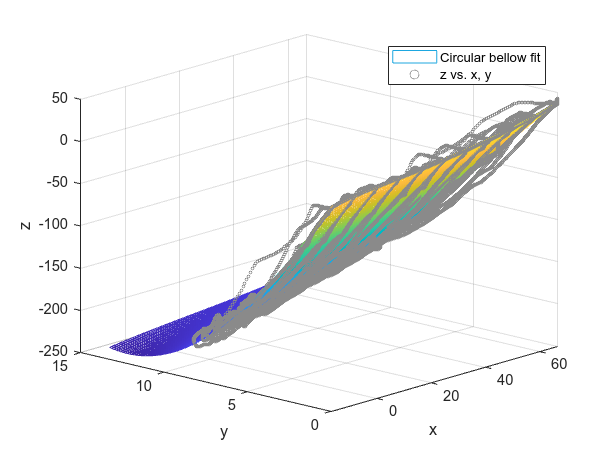


% Set up fittype and options.
ft = fittype( 'poly33' );

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
%h = plot( fitresult, [xData, yData], zData );
hold on
xlims = [min(xData), max(xData)];
ylims = [min(yData), max(yData)];
mesh_res = 100;
xs = linspace(xlims(1), xlims(2), mesh_res);
ys = linspace(ylims(1), ylims(2), mesh_res);
[X, Y] = meshgrid(xs, ys);
meshvals = fitresult(X(:), Y(:));
Z = reshape(meshvals, size(X));
mesh(X, Y, Z);
scatter3(xData, yData, zData, 4, [138 138 138]/255, 'o');
legend('Circular bellow fit', 'z vs. x, y', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'x', 'Interpreter', 'none' );
ylabel( 'y', 'Interpreter', 'none' );
zlabel( 'z', 'Interpreter', 'none' );
grid on
view( -48.0, 19.1 );

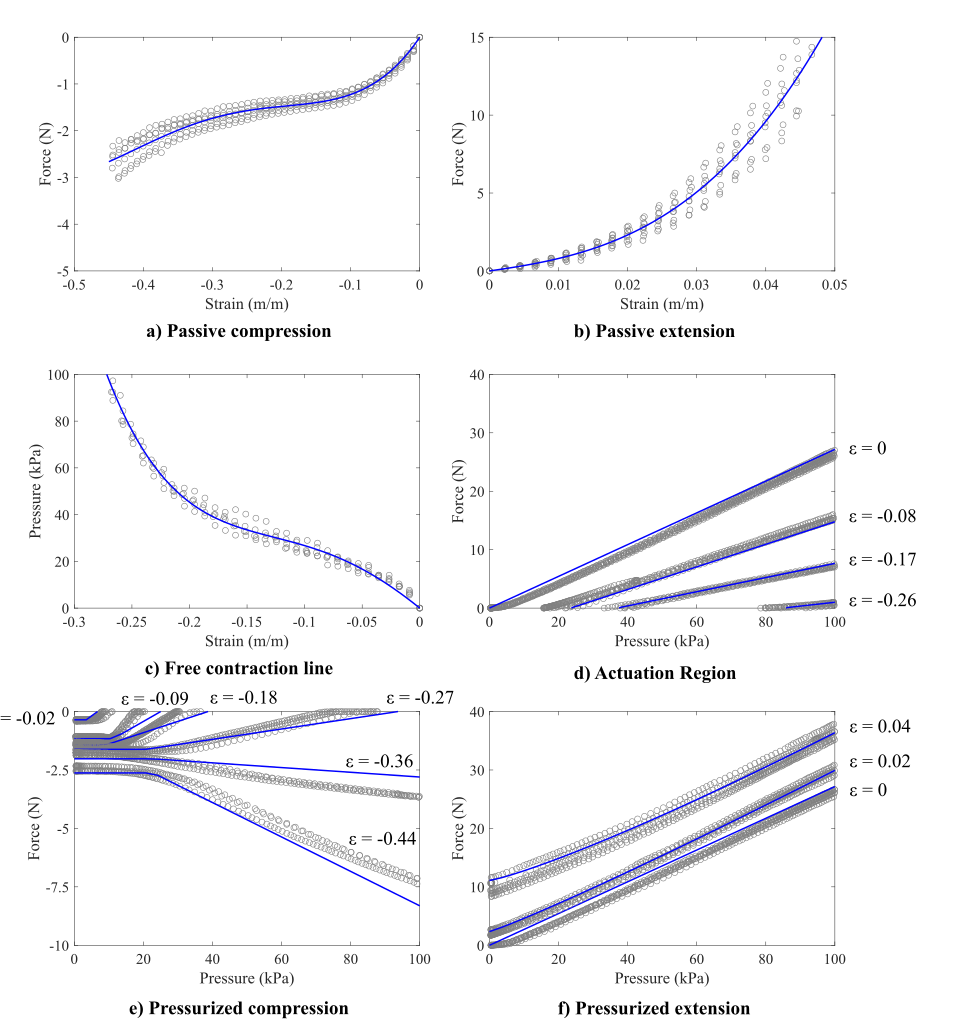

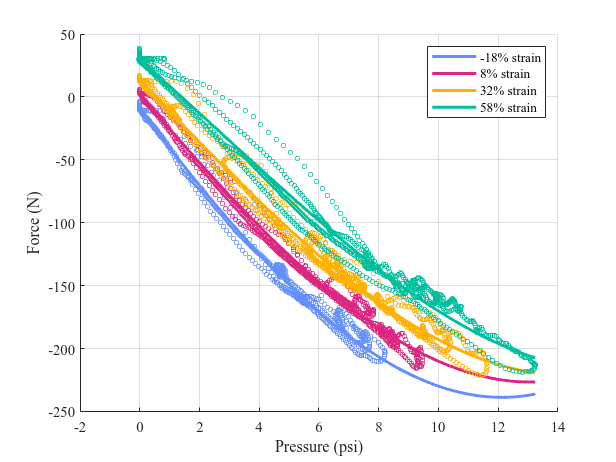

% Examine the quality of the fit by plotting plotting the fits at various
% fixed strains or pressures.
color_blue = [100 143 255] / 255;
color_red = [220 38 127] / 255;
color_yellow = [255 176 0] / 255;
color_green = [0, 191, 159] / 255;
colors = [color_blue; color_red; color_yellow; color_green];

% For each of five strains, fix strains and plot pressure-force
strains = all_datasets.TensileStrain_Displacement_;
[N_strains, edges_strains] = histcounts(strains);
hold_strains = edges_strains(N_strains > 1000);
strain_bin_ids = discretize(strains, hold_strains);

axes(figure(), "FontName", "Times")
hold on
count = 1;
legends = [];
for i = 1 : 3 : length(hold_strains)
    strain_i = hold_strains(i);
    i_at_strain = strain_bin_ids == i;
    %i_at_strain = i_at_strain(1:3:end);
    tab_at_strain = all_datasets(i_at_strain, :);
    tab_at_strain = tab_at_strain(1:3:end, :);
    plot(tab_at_strain.Pressure, tab_at_strain.Force, 'o', "Color", colors(count, :), "markersize", 3);
    plot(ys, fitresult(strain_i * ones(size(ys)), ys), "Color", colors(count, :), "linewidth", 2);
    
    count = count + 1;
    legends = [legends, '', sprintf("%d%% strain", strain_i)];
end
legend(legends)
grid on
xlabel("Pressure (psi)");
ylabel("Force (N)");

function tab_out = process_test(tab_instron, tab_pressure)
    % Smooth the pressures with a moving average
    pressure_smoothed = smoothdata(tab_pressure.Pressure, "gaussian", 200);
    
    % Interpolate pressures at the timestamps of the instron logs
    [pressure_times_unique, i_times] = unique(tab_pressure.Time);
    pressure_interp = interp1(pressure_times_unique, pressure_smoothed(i_times), tab_instron.Time);

    tab_out = tab_instron;
    tab_out.Pressure = pressure_interp;
end